# IMCL推定アルゴリズムの修正

検出点を信号最大値にしてしまうと，ノイズの影響を大きく受ける．そこで，相互相関をとり，時系列的にもっとも送信波形と似た形状の波形がある時刻を割出すことで検出の正確度を担保する．

対象：下の条件で得たデータ

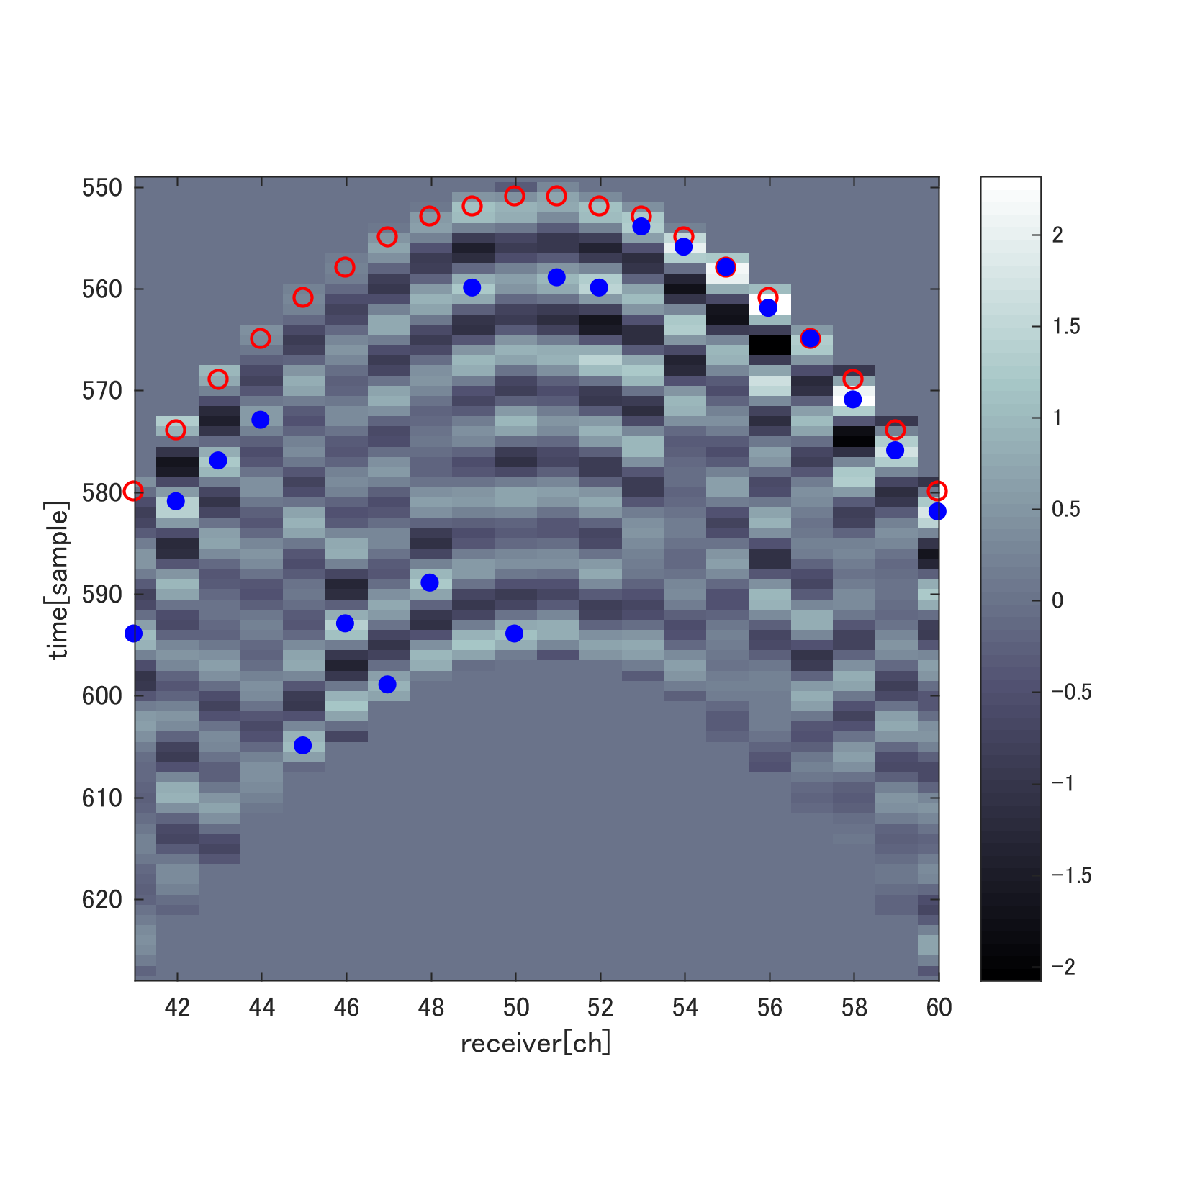

"H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_no_06_maxrfsignal_detect_boundary_case2

dst_path = 'H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_no_06_maxrfsignal_detect_boundary_case26\';
load([dst_path,'true2_assumption2\rfdata.mat']);
load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL2.0_pure\sourse_wave.mat")
[acor,lag] = xcorr(abs(hilbert(focused_rfdata_masked(:,52))),abs(hilbert(source_wave)),'coeff');
reference_point(1,52);
[~,I] = max(abs(acor));
lagDiff = lag(I)

lagDiff = 534

結果をまとめたほうがいいのではないか．

あまり改善にはつながっていないことはたしか．